- Matlab

% Limpiar Consola
close all
clc
clear all

- Teoria

% Matrices de rotacion
syms alpha beta gamma
Rz = [cosd(alpha) -sind(alpha) 0;
      sind(alpha) cosd(alpha) 0;
      0 0 1];

Ry = [cosd(beta) 0 sind(beta);
      0 1 0;
      -sind(beta) 0 cosd(beta)];

Rx = [1 0 0;
      0 cosd(gamma) -sind(gamma);
      0 sind(gamma) cosd(gamma)];

R1 = Rz*Ry*Rx;

- Matriz generica

% Representacion de una Matriz
syms R11 R12 R13 R21 R22 R23 R31 R32 R33
R = [R11 R12 R13;
     R21 R22 R23;
     R31 R32 R33];

- Apartado Teorico

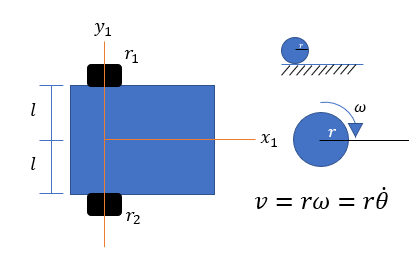

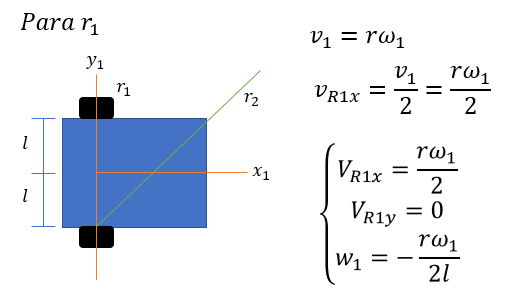      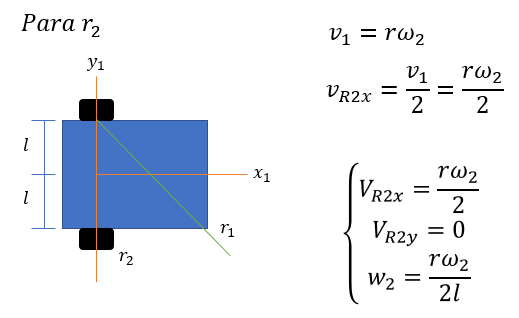

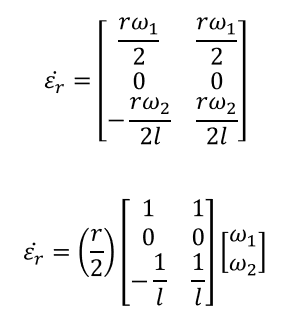         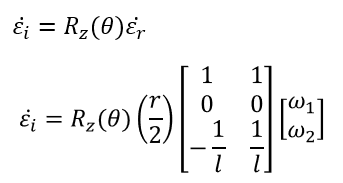

# Ejercicio 1

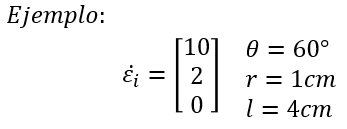

% Variables
syms xi_i theta r l omega_1 omega_2 epsilon_1 xi_r

% Datos
xi_i = [10;5;0];
theta = 60;
r = 1; %cm
l = 4; %cm

% Solucion
xi_r =[omega_1;omega_2];
Rz = subs(Rz,alpha,theta); % Reemplaza el valor de alpha por theta

% pinv sirve para sacar la pseudo inversa de una matriz
% inv sirve para sacar la inversa de una matriz 

xi_r == vpa((2/r)*(pinv([1 1;0 0;-1/l 1/l]))*(inv(Rz))*xi_i,3)

$$ans = \left(\begin{array}{c} \omega_{1}=9.3301270189695060253143310546875\\ \omega_{2}=9.3301270189695060253143310546875 \end{array}\right)$$